# Get Started with WLAN System-Level Simulation in MATLAB

This example shows how to model a WLAN network consisting of an IEEE® 802.11ax™ [1] access point (AP) and a station (STA) by using WLAN Toolbox™ and the Communications Toolbox™ Wireless Network Simulation Library.

Using this example, you can:

- Simulate a multinode WLAN system by configuring the application layer (APP), medium access control (MAC), and physical layer (PHY) parameters at each node.

- Model uplink and downlink communication between an AP and a STA.

- Switch between the abstracted and full models of MAC and PHY layers.

- Visualize the time spent by each node in Idle, Contention, Transmission, and Reception state.

- Capture the APP, MAC, and PHY statistics for each node.

The simulation results show performance metrics such as throughput, latency, and packet loss.

Additionally, you can use this example script to perform these tasks.

- Configure IEEE 802.11be Compliant Frame Transmissions

- Add Mobility To Nodes

- Configure External Application Traffic

- Capture IQ Samples

## WLAN System-Level Simulation

This example shows you how to model a WLAN network with uplink and downlink communication between an AP and a STA. This figure illustrates the example network.

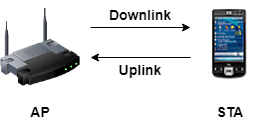

This figure shows the example workflow.

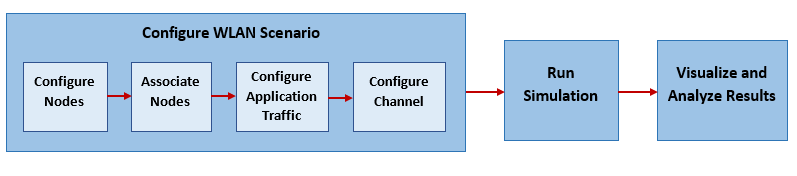

To confirm compliance with the IEEE 802.11 standard [2], the features in this example are validated with Box-3 and Box-5 scenarios specified in the TGax evaluation methodology [4]. The network throughputs that are calculated for TGax simulation scenarios [5] are validated against the published calibration results from the TGax Task Group.

## Check for Support Package Installation

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

## Configure Simulation Parameters

Set the seed for the random number generator to `1`. The seed value controls the pattern of random number generation. The random number generated by the seed value impacts several processes within the simulation, including backoff counter selection at the MAC layer and predicting packet reception success at the physical layer. To improve the accuracy of your simulation results after running the simulation, you can change the seed value, run the simulation again, and average the results over multiple simulations.

rng(1,"combRecursive")

Specify the simulation time in seconds. To visualize a live state transition plot for all of the nodes, set the `enablePacketVisualization` variable to `true`. To view the node performance visualization, set the `enableNodePerformancePlot` variable to `true`.

simulationTime = 1;
enablePacketVisualization = true;
enableNodePerformancePlot = true;

At the transmitter and receiver, modeling full MAC processing involves complete MAC frame generation at the MAC layer. Similarly, modeling full PHY processing involves complete operations related to waveform transmission and reception through a fading channel. When simulating large networks, full MAC and PHY processing is computationally expensive.

In the abstracted MAC, the node does not generate or decode any frames at the MAC layer. Similarly, in the abstracted PHY, the node does not generate or decode any waveforms at the PHY. MAC and PHY abstraction enable you to minimize the complexity and runtime of system-level simulations. For more information on PHY abstraction, see the [Physical Layer Abstraction for System-Level Simulation](docid:wlan_ug#example-PHYAbstractionExample) example.

This table shows you how to switch between the abstracted and full MAC or PHY by configuring the values of the `MACFrameAbstraction` and `PHYAbstractionMethod` properties of [`wlanNode`](docid:wlan_ref#mw_object_wlanNode) object.

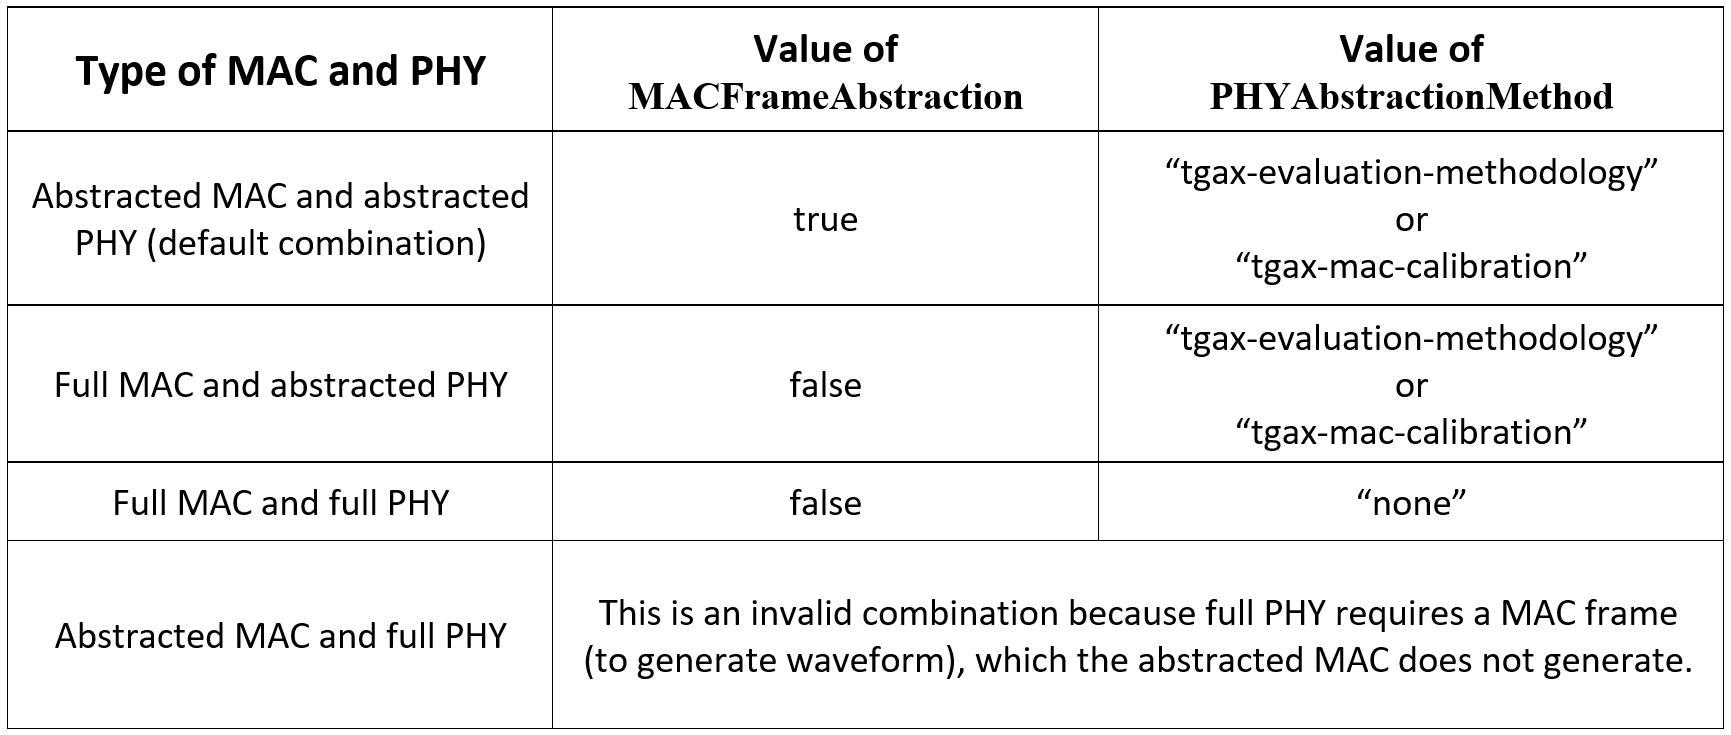

If you set the `PHYAbstractionMethod` to `tgax-evaluation-methodology`, the PHY estimates the performance of a link with the TGax channel model by using an effective signal-to-interference-plus-noise ratio (SINR) mapping. Alternatively, if you set the `PHYAbstractionMethod` to `tgax-mac-calibration` the PHY assumes a packet failure on interference without actually calculating the link performance. To use the full PHY, set the value of `PHYAbstractionMethod` to `none`.

MACFrameAbstraction = false;
PHYAbstractionMethod = "tgax-evaluation-methodology";

The example demonstrates packet capture at both AP and STA nodes. The packet capture (PCAP) or packet capture next generation (PCAPNG) file (.pcap or .pcapng, respectively) is a widely used packet capture file format to perform packet analysis. The packets are captured into a PCAP file in this example. To capture the packets exchanged during the simulation, set the `capturePacketsFlag` flag to `true`.

capturePacketsFlag = true;

## Configure WLAN Scenario

Initialize the wireless network simulator by using the [`wirelessNetworkSimulator`](docid:comm_ref#mw_d18d4a33-0cf8-49d9-abb5-a4cfa0de673d) object.

networkSimulator = wirelessNetworkSimulator.init;

### Nodes

The [`wlanDeviceConfig`](docid:wlan_ref#mw_object_wlanDeviceConfig) object enables you to set the configuration parameters for the AP and STA. Create two WLAN device configuration objects, one for the AP and the other for the STA. Specify the operating mode, modulation and coding scheme, and transmission power (in dBm) for the AP and STA.

accessPointCfg = wlanDeviceConfig(Mode="AP",MCS=2,TransmitPower=15); % AP device configuration
stationCfg = wlanDeviceConfig(Mode="STA",MCS=2,TransmitPower=15);    % STA device configuration

To create an AP node and a STA node from the specified WLAN device configurations, use [`wlanNode`](docid:wlan_ref#mw_object_wlanNode) objects. Specify the name and position of the AP and the STA. Specify the PHY abstraction method used for the AP and the STA. Configure the `MACFrameAbstraction` property of the `wlanNode` object to indicate if the MAC frames are abstracted by the nodes.

accessPoint = wlanNode(Name="AP", ...
    Position=[10 0 0], ...
    DeviceConfig=accessPointCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

station = wlanNode(Name="STA", ...
    Position=[20 0 0], ...
    DeviceConfig=stationCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

Create a WLAN network consisting of the AP and the STA.

nodes = [accessPoint station];

To ensure all the nodes are configured properly, use the [`hCheckWLANNodesConfiguration`](matlab:edit("hCheckWLANNodesConfiguration.m")) helper function.

hCheckWLANNodesConfiguration(nodes)

### Association and Application Traffic

Associate the STA to the AP by using the [`associateStations`](docid:wlan_ref#mw_function_associateStations) object function of the wlanNode object. To configure uplink and downlink application traffic between the AP and STA, use the `FullBufferTraffic` argument of the `associateStations` object function.

associateStations(accessPoint,station,FullBufferTraffic="on");

### Wireless Channel

To model a random TGax fading channel between each node, this example uses the [`hSLSTGaxMultiFrequencySystemChannel`](matlab:edit("hSLSTGaxMultiFrequencySystemChannel.m")) helper object. Add the channel model to the wireless network simulator by using the [`addChannelModel`](docid:comm_ref#mw_17054773-3d39-4e39-8566-5fac05380a1e) object function of the `wirelessNetworkSimulator` object.

channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn)

### Export WLAN MAC Frames to PCAP or PCAPNG File

Create a [`hExportWLANPackets`](matlab:edit("hExportWLANPackets.m")) helper object to generate PCAP files. Specify the node objects at which you want to capture the packets. The helper object captures transmitted and received packets at each of these nodes and generates a PCAP file for each node. If you want to capture the packets in a PCAPNG file, specify the string "pcapng" as the second argument to the object function call. Note that capturing packets is possible only when `MACFrameAbstraction` flag is set to `false`.

if capturePacketsFlag
    clear capturePacketsObj;                       % Clear existing helper object
    capturePacketsObj = hExportWLANPackets(nodes);
end

You can visualize and analyze the PCAP or PCAPNG file by using a third-party packet analyzer tool such as Wireshark.

## Simulation and Results

Add the nodes to the wireless network simulator.

addNodes(networkSimulator,nodes)

To view the state transition plot, use the [`hPlotPacketTransitions`](matlab:edit("hPlotPacketTransitions.m")) helper object. To disable the packet communication over frequency subplot, set the `FrequencyPlotFlag` property of `hPlotPacketTransitions` helper object to `false`.

if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

To view the node performance visualization, use the [`hVisualizePerformance`](matlab:edit("hVisualizePerformance.m")) helper object.

if enableNodePerformancePlot
    performancePlotObj = hVisualizePerformance(nodes,simulationTime);
end

Run the network simulation for the specified simulation time. The runtime visualization shows the time spent by the AP and the STA in Idle, Contention, Transmission, and Reception state.

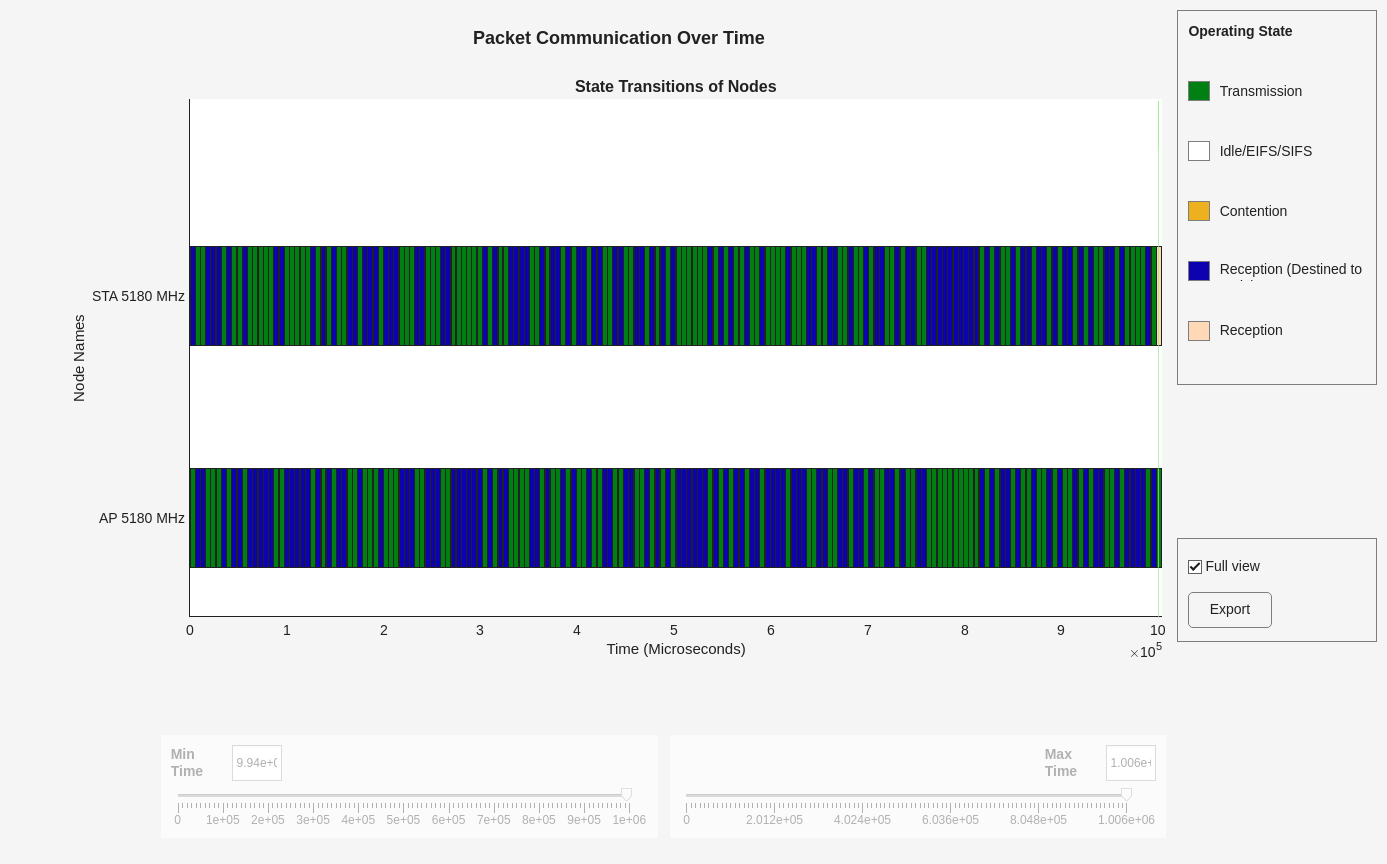

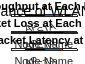

run(networkSimulator,simulationTime);

The preceding figure displays these simulation plots.

- Throughput (in Mbps) at each transmitter (AP and STA).

- Packet loss ratio (ratio of unsuccessful data transmissions to the total data transmissions) at each transmitter (AP and STA).

- Average packet latency incurred at each receiver (AP and STA). The average packet latency shows the average latency that the STA incurs to receive the downlink traffic from the AP and the average latency that the AP incurs to receive uplink traffic from the STA.

Retrieve the APP, MAC, and PHY statistics at each node by using the [`statistics`](docid:wlan_ref#mw_function_wlanstatistics) object function of the `wlanNode` object. For more information about the statistics, see [WLAN System-Level Simulation Statistics](docid:wlan_ug#mw_cbfaee30-7467-406f-84ad-20230f9245e2).

stats = statistics(nodes);

Because the `hExportWLANPackets` helper object does not overwrite the existing PCAP or PCAPNG file, deleting the PCAP objects used in this simulation.

if capturePacketsFlag
    delete(capturePacketsObj.PCAPObjList);
end

## Further Exploration

You can use this example to further explore these functionalities.

### Configure IEEE 802.11be Compliant Frame Transmissions

This code enables you to perform these steps.

- Configure the PHY transmission format of the WLAN device as "EHT-SU", and the modulation and coding scheme as 13.

- Assign the WLAN device configuration to the `DeviceConfig` property of the [`wlanNode`](docid:wlan_ref#mw_object_wlanNode) object.

% accessPointCfg = wlanDeviceConfig(Mode="AP",TransmissionFormat="EHT-SU",MCS=13);
% accessPoint = wlanNode(DeviceConfig=accessPointCfg);

To configure IEEE 802.11be [3] compliant frame transmissions, create an AP by using the preceding code and run the example.

### Add Mobility To Nodes

You can add mobility to any node by using the [`addMobility`](docid:wlan_ref#mw_de7d84db-97bb-454a-8b9c-c50ee88ea2d7) object function. To add mobility to the STA node, uncomment and add this code before you run the wireless network simulator.

% addMobility(station)

### Configure External Application Traffic

To generate and add external application traffic pattern (On-Off, Video, Voice, and FTP) to the WLAN nodes, modify the traffic configuration in this example. To generate an On-Off application traffic, create two [`networkTrafficOnOff`](docid:comm_ref#mw_0b2cd92a-350a-4264-9283-db5da34bd041) objects for downlink and uplink traffic, respectively. Configure these objects by specifying the application data rate, packet size, On time, and Off time.

trafficSourceDL = networkTrafficOnOff(DataRate=100000,PacketSize=1500,OnTime=Inf,OffTime=0);
trafficSourceUL = networkTrafficOnOff(DataRate=100000,PacketSize=1500,OnTime=Inf,OffTime=0);

Attach downlink application traffic from the AP node to the STA node by using the [`addTrafficSource`](docid:wlan_ref#mw_function_wlanaddTrafficSource) object function of the [`wlanNode`](docid:wlan_ref#mw_object_wlanNode) object. Similarly, attach uplink application traffic from the STA node to the AP node.

addTrafficSource(accessPoint,trafficSourceDL,DestinationNode=station,AccessCategory=0);

Error using wlanNode/addTrafficSource
Cannot add traffic source to AP because full buffer traffic for access category 0 is enabled on this node.

addTrafficSource(station,trafficSourceUL,DestinationNode=accessPoint,AccessCategory=0);

To generate video, voice, and FTP application traffic, use the [`networkTrafficVideoConference`](docid:comm_ref#mw_59b5e5bb-0f1a-48ce-847d-72fe2ad1a842), [`networkTrafficVoIP`](docid:comm_ref#mw_6c2e45f3-4c26-4eb7-9cde-ce2a6ad3552d), and [`networkTrafficFTP`](docid:comm_ref#mw_55f51c4d-641c-4ecf-a6c2-9b3aa9f3ba2a) objects, respectively`.`

### Capture IQ Samples

Capture the IQ samples of the nodes by using the [`hCaptureIQSamples`](matlab:edit("hCaptureIQSamples.m")) helper object. Uncomment and add this code before you run the wireless network simulator.

% for nodeIdx = 1:numel(nodes)
%     iqSampleObj(nodeIdx) = hCaptureIQSamples(nodes(nodeIdx));
% end

At the end of the simulation, the simulation stores the IQ samples of the corresponding nodes in a MAT file with the filename format `NodeName``_``NodeID``_``yyyyMMdd``_``HHmmss``.``mat`, where:

- `NodeName` — Name of the node.

- `NodeID` — Numeric ID of the node.

- `yyyyMMdd` — Date of file creation, in the format year, month, day.

- `HHmmss` — Time of file creation, in the format hour, minute, second, using the 24-hour clock format.

The `IQSamples` property of the `iqSampleObj` object contains the captured IQ samples. If the network contains several nodes or when the simulation time is long, the process of capturing the IQ samples consume significant memory. The MAT file generated at the end of the simulation can consume significant disk space. For example, a system-level simulation that captures 100 million IQ samples creates a MAT file of approximate size 1.5 GB.

To visualize the captured IQ samples, use the [`signalAnalyzer`](docid:signal_ref#bulfy0x) app. For example, to visualize the IQ samples captured at the AP, uncomment this code.

% signalAnalyzer(iqSampleObj(1).IQSamples);

## Appendix

This example uses these helpers:

- [`hCheckWLANNodesConfiguration`](matlab:edit("hCheckWLANNodesConfiguration.m")) — Check if the node parameters are configured correctly

- [`hExportWLANPackets`](matlab:edit("hExportWLANPackets.m")) — Capture MAC frames and write them into a PCAP/PCAPNG file

- [`hSLSTGaxMultiFrequencySystemChannel`](matlab:edit("hSLSTGaxMultiFrequencySystemChannel.m")) — Return a system channel object

- [`hSLSTGaxAbstractSystemChannel`](matlab:edit("hSLSTGaxAbstractSystemChannel.m")) — Return a channel object for abstracted PHY layer

- [`hSLSTGaxSystemChannel`](matlab:edit("hSLSTGaxSystemChannel.m")) — Return a channel object for full PHY layer

- [`hSLSTGaxSystemChannelBase`](matlab:edit("hSLSTGaxSystemChannelBase.m")) — Return the base channel object

- [`hPlotPacketTransitions`](matlab:edit("hPlotPacketTransitions.m")) — Plot the state transition figure

- [`hVisualizePerformance`](matlab:edit("hVisualizePerformance.m")) — Plot the performance metrics figure

- [`hCaptureIQSamples`](matlab:edit("hCaptureIQSamples.m")) — Capture the IQ samples of a node.

## References

- "IEEE Standard for Information Technology--Telecommunications and Information Exchange between Systems Local and Metropolitan Area Networks--Specific Requirements Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications Amendment 1: Enhancements for High-Efficiency WLAN." IEEE. [https://doi.org/10.1109/IEEESTD.2021.9442429](https://doi.org/10.1109/IEEESTD.2021.9442429).

- "IEEE Standard for Information Technology--Telecommunications and Information Exchange between Systems - Local and Metropolitan Area Networks--Specific Requirements Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications." IEEE. [https://doi.org/10.1109/IEEESTD.2021.9363693](https://doi.org/10.1109/IEEESTD.2021.9363693).

- “IEEE Draft Standard for Information Technology–Telecommunications and Information Exchange between Systems Local and Metropolitan Area Networks–Specific Requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications Amendment: Enhancements for Extremely High Throughput (EHT).” *IEEE P802.11be/D3.0, January 2023*, March 2023, 1–999. [https://ieeexplore.ieee.org/servlet/opac?punumber=10058124](https://ieeexplore.ieee.org/servlet/opac?punumber=10058124).

- IEEE P802.11 Wireless LANs - 11ax Evaluation Methodology. IEEE 802.11-14/0571r12. IEEE, January 2016.

- IEEE P802.11 Wireless LANs - TGax Simulation Scenarios. IEEE 802.11-14/0980r16. IEEE, July 2015.

*Copyright 2021-2023 The MathWorks, Inc.*